#### PCB Layout

Component placement (LEDs, mounting holes)

circ_rad = 30;
led_rad = 25;
positions = 8;
led_coords = [];
x_cent = 107.5;
y_cent = 77.5;    
for i = 1:positions
   led_coords(i,1) = x_cent + led_rad * cos(i*2*pi/positions);
   led_coords(i,2) = y_cent + led_rad * sin(i*2*pi/positions);
end
led_coords

led_coords =   125.1777   95.1777
  107.5000  102.5000
   89.8223   95.1777
   82.5000   77.5000
   89.8223   59.8223
  107.5000   52.5000
  125.1777   59.8223
  132.5000   77.5000


theta = linspace(0,2*pi);
perim_x = x_cent + circ_rad * cos(theta);
perim_y = y_cent + circ_rad * sin(theta);
scatter(led_coords(:,1), led_coords(:,2),'gs', 'LineWidth',15)
hold on
plot(perim_x,perim_y)
axis equal
mounting_rad = 24;
hole_rad = 3.5;
holeangle = [26 153 -108];
for j = 1:length(holeangle)
    holex = x_cent + mounting_rad * cosd(holeangle(j)) + hole_rad .* cos(theta);
    holey = y_cent + mounting_rad * -sind(holeangle(j)) + hole_rad .* sin(theta);
    mountingHolePos = [x_cent + mounting_rad * cosd(holeangle(j)) y_cent + mounting_rad * -sind(holeangle(j))]
    plot(holex,holey)
end

mountingHolePos =   129.0711   66.9791


mountingHolePos =    86.1158   66.6042


mountingHolePos =   100.0836  100.3254


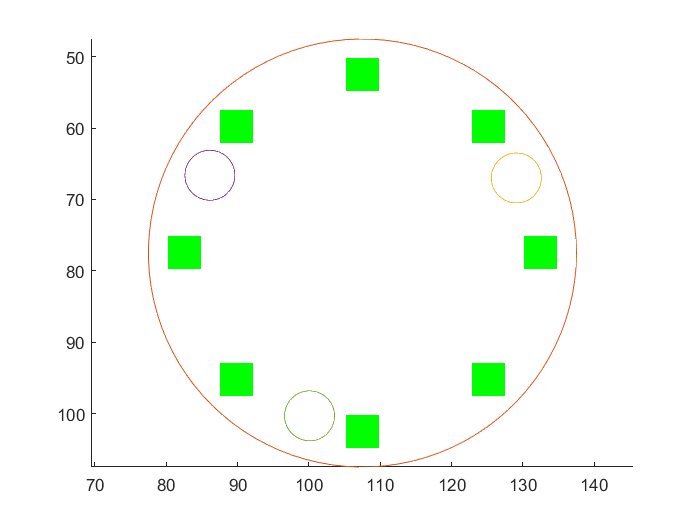

set(gca,'ydir','reverse')
hold off

Calculate position of capacitor for .POS file exporting (KiCAD will not put the positions of through hole components, so the capacitor must be interpolated from nearby component data)

%POS file
PCB_x = [3.409 3.651 3.997];
PCB_y = [2.289 2.634 2.457];
POS_x = [-20.8964 -14.761 -5.9726];
POS_y = [19.35115 10.576 15.0746];
x = polyfit(PCB_x,POS_x,1);
cap_pcb_x = 3.785468543;
cap_pos_x = x(1) * cap_pcb_x + x(2)

cap_pos_x = -11.3435

y = polyfit(PCB_y, POS_y, 1);
cap_pcb_y = 2.373750512;
cap_pos_y = y(1) * cap_pcb_y + y(2)

cap_pos_y = 17.1943

#### Component choices

Checking the behavior of C4 (Supercapacitor) and R1 (Shield resistor). Results suggest using PWM to adjust the charging voltage of C4, as suggested below. Suggested charging curve of 


$$\textrm{Duty}\;\textrm{Cyle}=\textrm{constrain}\left(0\ldotp 1+0\ldotp 1t,\;0,\;1\right)$$


where t is in seconds.

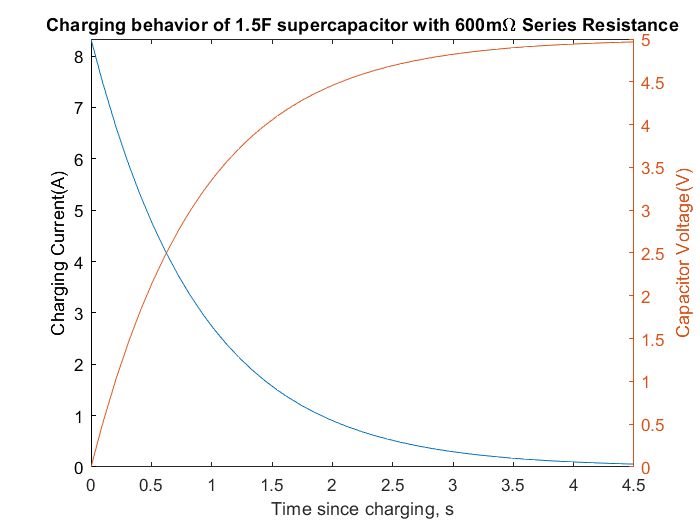

%supercapacitor charging
clear all
close all
syms t T const f
R = .6;
C = 1.5;
tau = R*C;
Vmax = 5;
V(t) = Vmax * (1-(exp(-t/tau)));
I(t) = Vmax/R * exp(-t/tau);
fplot(I(t))
hold on
ylabel("Charging Current(A)")
yyaxis right
fplot(V(t))
ylabel("Capacitor Voltage(V)")
xlim([0 5*tau])
xlabel("Time since charging, s")
title('Charging behavior of 1.5F supercapacitor with 600m\Omega Series Resistance')
hold off

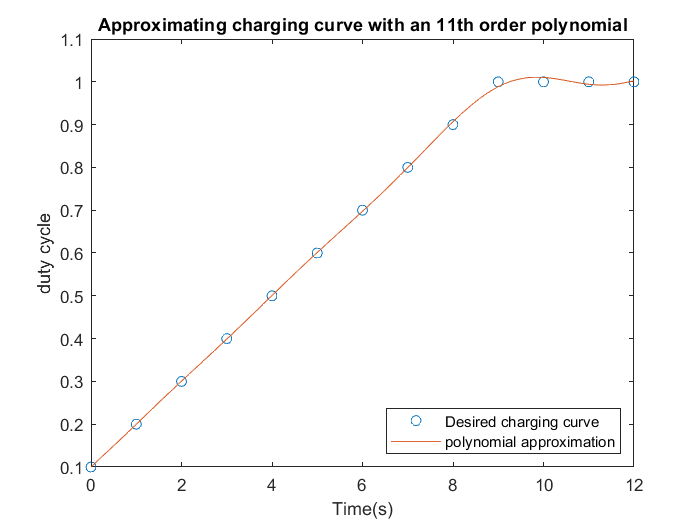

charging_curve = [
    0 0.1;
    1 0.2;
    2 0.3;
    3 0.4;
    4 0.5;
    5 0.6;
    6 0.7;
    7 0.8;
    8 0.9;
    9 1;
    10 1;
    11 1;
    12 1;
    13 1
    14 1];
p = polyfit(charging_curve(:,1), charging_curve(:,2), 11);
f(t) = 0;
for i = 1:length(p)
    f(t) = p(i) * t^(length(p)-i) + f(t);
end
figure
plot(charging_curve(:,1),charging_curve(:,2), 'o')
hold on
fplot(f(t))
xlim([0 12])
legend('Desired charging curve', 'polynomial approximation', 'Location', 'southeast')
xlabel('Time(s)')
ylabel('duty cycle')
title('Approximating charging curve with an 11th order polynomial')

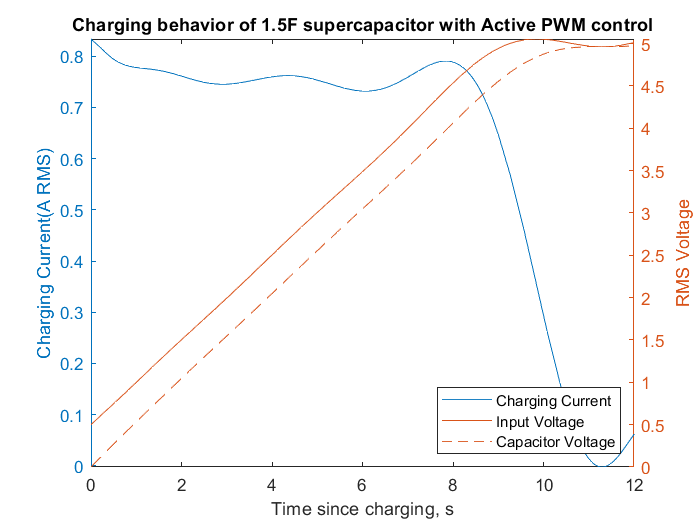

V_pwm_in(t) = f(t) * 5;
Q(t) = exp(-t/(R*C)) * (const + int(V_pwm_in(t)/R * exp(t/(R*C))));
new_const = solve(Q(0) == 0, const);
Q(t) = subs(Q(t), const, new_const);
figure
yyaxis left
I_pwm(t) = diff(Q(t));
fplot(I_pwm(t))
hold on
ylabel("Charging Current(A RMS)")
yyaxis right
fplot(V_pwm_in(t))
ylabel("RMS Voltage")
V_res(t) = I_pwm(t) * R;
V_cap(t) = V_pwm_in(t) - V_res(t);
fplot(V_cap(t))
xlim([0 12])
xlabel("Time since charging, s")
title('Charging behavior of 1.5F supercapacitor with Active PWM control')
legend('Charging Current', 'Input Voltage', 'Capacitor Voltage', 'Location','southeast')
hold off

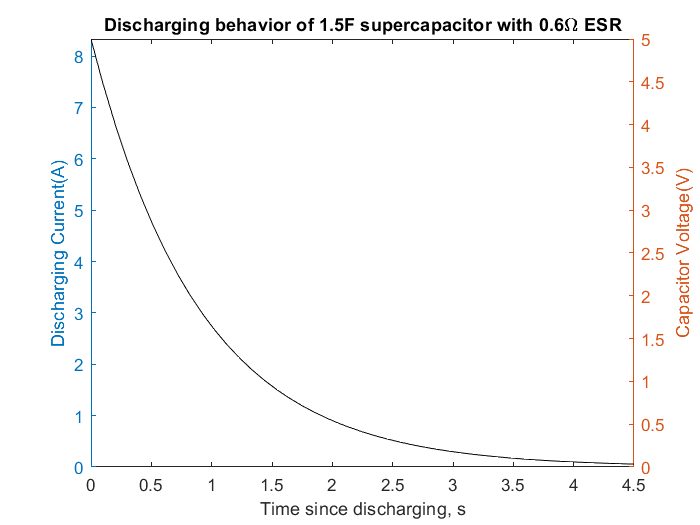

figure
R = 0.6;
tau = R * C;
V(t) = Vmax * ((exp(-t/tau)));
I(t) = Vmax/R * exp(-t/tau);
yyaxis left
fplot(I(t), 'k')
hold on
ylabel("Discharging Current(A)")
yyaxis right
fplot(V(t), 'k')
ylabel("Capacitor Voltage(V)")
xlim([0 5*tau])
xlabel("Time since discharging, s")
title('Discharging behavior of 1.5F supercapacitor with 0.6\Omega ESR')
hold off

figure
U(t) = int(I(t)*V(t));
constant = U(0);
U(t) = U(t) - constant;
% fplot(U(t))
% hold on
% power_loss(t) = I(t)^2 * R;
% energy_loss(t) = int(power_loss(t));
% constant = energy_loss(0);
% energy_loss(t) = energy_loss(t) - constant;
% %fplot(energy_loss(t))
% xlim([0 5*tau])
% ylabel('Energy(J)')
% yyaxis right
% fplot(power_loss(t), 'm')
% ax = gca;
% ax.YAxis(1).Color = 'k';
% ax.YAxis(2).Color = 'k';
% hold off
% legend('energy stored = energy lost', 'power loss')
% ylabel("Power loss(W)")
% xlabel('time(s)')
% title('Energy storage and loss in capacitor due to ESR')
steel_wool_weight = 4;%g
c = .046; %J/g*K
temperature_increase_of_steel_wool_after_discharge = solve(U(20) == steel_wool_weight * c * T,T)

$$temperature\_increase\_of\_steel\_wool\_after\_discharge = 101.9022$$

R_shield = 500

R_shield = 500

drain_tau = R_shield*C/60 %1K resistor, tau in mins

drain_tau = 12.5000

max_power_shield_resistor = 5^2 / R_shield

max_power_shield_resistor = 0.0500

resistance_value_ok = max_power_shield_resistor < 1/16

resistance_value_ok = logical
   1


%charge/discharge FET turn on time
Q_gate1 = 5 * 10^-9;
I_gate1 = .02;
turn_on_off_time1 = Q_gate1/I_gate1

turn_on_off_time1 = 2.5000e-07

Q_gate2 = 15 * 10^-9;
I_gate2 = 5/(300); %limited by pullup resistor
turn_off_time2 = Q_gate2/I_gate2

turn_off_time2 = 9.0000e-07

pwm_frequency = 5*10^3;
period = 1/pwm_frequency;
pwm_min_on_period = 1/10 * 1/pwm_frequency

pwm_min_on_period = 2.0000e-05

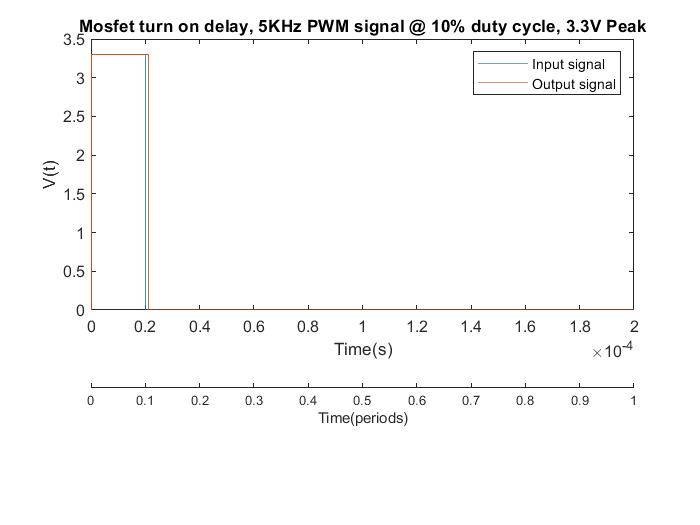

input_wave(t) = piecewise(t < pwm_min_on_period, 3.3, t>pwm_min_on_period, 0);
output_wave(t) = piecewise(t<(turn_on_off_time1), 0, t>turn_on_off_time1 & t<pwm_min_on_period+turn_off_time2+turn_on_off_time1, 3.3,t>pwm_min_on_period+turn_off_time2+turn_on_off_time1, 0 );
figure
fplot(input_wave(t)) 
hold on
fplot(output_wave(t))
xlim([0 2*10^-4])
ylim([0 3.5])
legend('Input signal', 'Output signal')
ylabel('V(t)')
title('Mosfet turn on delay, 5KHz PWM signal @ 10% duty cycle, 3.3V Peak')
ax1 = gca;
axPos = ax1.Position;
ax1.Position = axPos + [0 0.3 0 -0.3];
ax2 = axes('position', (axPos .* [1 1 1 1e-3]) + [0 0.15 0 0], 'color', 'none');
ax2.XLim = [0 1];
ax1.XLabel.String = 'Time(s)';
ax2.XLabel.String = 'Time(periods)';

#### Battery life calculations

u = symunit;
battery_capacity = 3.5*([u.A]*[u.h]);%Ah
nominal_voltage = 3.7*[u.V];
buck_efficiency = .95;
capacitance = 1.5*[u.C]/[u.V];
charging_voltage = 5*[u.V];
charge_efficiency = 0.5;
energy_per_capacitor_charge = 1/2*capacitance * charging_voltage^2 * 1/3600 * [u.V]*[u.A]*[u.h] / [u.J] * [u.J]/([u.V] * [u.C])

$$energy\_per\_capacitor\_charge = 0.0052\,A\,V\,h$$

LED_power_draw = 8*5*[u.V]*.05*[u.A];%each LED draws 50mA @ 5V, source 
% https://www.pololu.com/product/2547#:~:text=Each%20RGB%20LED%20draws%20approximately%2050%20mA%20when%20it%20is,and%20powered%20at%205%20V.
ESP_power_draw = 5*[u.V] * [.070 .300]*[u.A];% assume 70-300mA current draw @ 5V (voltage is at 5V from the LDO that powers the ESP)
%https://www.esp8266.com/viewtopic.php?t=3875
battery_energy = battery_capacity*nominal_voltage;
battery_life = buck_efficiency * battery_energy ./ (LED_power_draw+ESP_power_draw) %h

$$battery\_life = \left(\begin{array}{cc} 5.2351\,h & 3.5150\,h \end{array}\right)$$

battery_life_loss_one_capacitor_discharge = battery_life - buck_efficiency * (battery_energy - energy_per_capacitor_charge/charge_efficiency) ./ (LED_power_draw+ESP_power_draw) %h

$$battery\_life\_loss\_one\_capacitor\_discharge = \left(\begin{array}{cc} 0.0042\,h & 0.0028\,h \end{array}\right)$$

actual_current_draw = [
    4.06 0.6;
    3.8 0.638;
    3.6 0.675;
    3.4 0.712;
    3.3 0.734;
    3.2 0.759;
    3.1 0.780;
    ] .* [u.V u.A]; %max LED brightness, 1st column is input voltage, 2nd column is input current
actual_power_draw = mean(actual_current_draw(:,1) .* actual_current_draw(:,2), 'all')

$$actual\_power\_draw = 2.4257\,A\,V$$

actual_battery_life = battery_energy / actual_power_draw

$$actual\_battery\_life = 5.3386\,h$$


%assume all other components are negligible in power draw

#### Checking delay RC circuits on the reset pin

%reset circuit
clear all
close all
t = linspace(0,.1);
Vcc = 3.3;
R = 10000;
C = 10^-6;
V_low = Vcc .* exp(-t./(R*C));

t_new = t + max(t);
V_high = Vcc .* (1-exp(t/(-R*C)));

times = [t t_new];
Voltage_curve = [V_low V_high];
plot(times, Voltage_curve)
hold on
plot([0 max(t_new)], [.25 * Vcc .25*Vcc])
plot([0 max(t_new)], [.75 * Vcc .75*Vcc])
enable_delay_time = min(t(V_low <= .25 * Vcc));
enable_delay_time_ms = 1000 * min(t(V_low <= .25 * Vcc))

enable_delay_time_ms = 14.1414

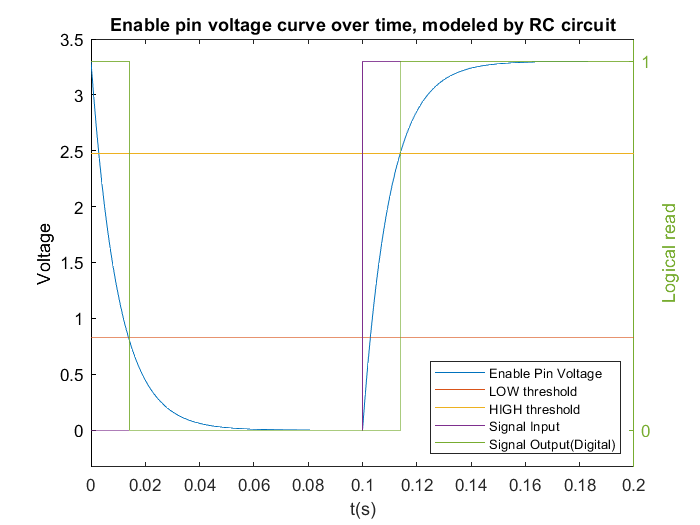

input_curve = Vcc * [0 0 1 1];
input_time = [0 0.1 0.1 0.2];
plot(input_time,input_curve)
ylabel("Voltage")
ylim([-0.1*3.3 3.5])
yyaxis right
plot([0, enable_delay_time, enable_delay_time, enable_delay_time + 0.1, enable_delay_time + 0.1, 0.2], [1 1 0 0 1 1])
legend(["Enable Pin Voltage", "LOW threshold", "HIGH threshold", "Signal Input", "Signal Output(Digital)"],'FontSize',8, 'location', 'southeast')
ylabel("Logical read")
ylim([-0.1 3.5/3.3])
yticks([0 1])
xlabel("t(s)")
title("Enable pin voltage curve over time, modeled by RC circuit")
hold off

#### Calculations for the acceleration that is measured by the accelerometer while spinning

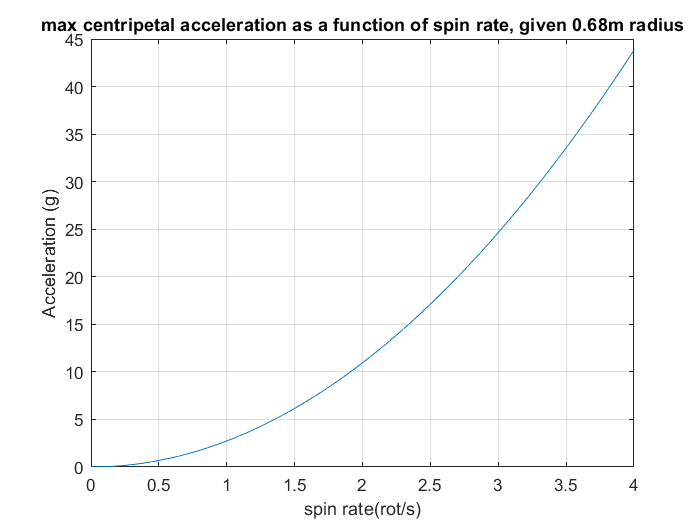

clear all
close all
r = .68;
spin_rate = linspace(0,4);
accel_gs = (spin_rate * 2 * pi) .^2 * r/9.8;
plot(spin_rate, accel_gs)
xlabel("spin rate(rot/s)")
ylabel("Acceleration (g)")
title("max centripetal acceleration as a function of spin rate, given 0.68m radius")
grid on

Distance traveled by poi head (Maximum) during one PWM cycle of the WS2812B LEDs

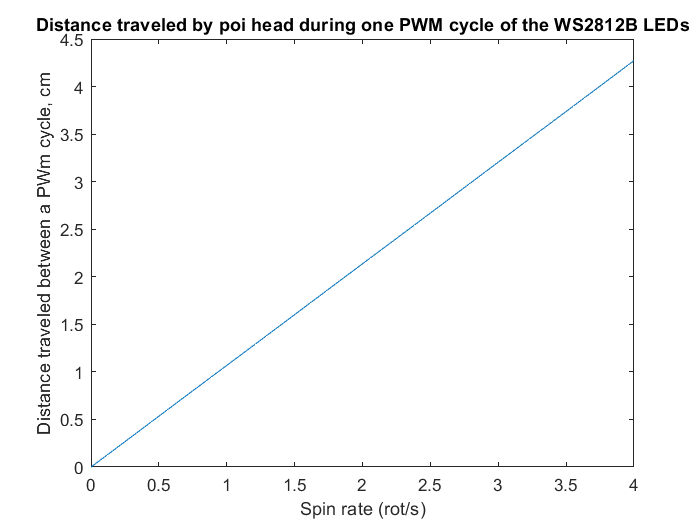

PWM_rate = 400;%Hz
spin_rate = linspace(0,4);
period = 1/PWM_rate;%sec
velocity = spin_rate * 2*pi*r;
distance_traveled = velocity * period;
plot(spin_rate, distance_traveled * 100)
xlabel("Spin rate (rot/s)")
ylabel("Distance traveled between a PWm cycle, cm")
title("Distance traveled by poi head during one PWM cycle of the WS2812B LEDs")